% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=x; T=2; [0;1]
% Expand in a seris by sines.

clear
syms x real;
syms pi;
f(x)=x;
L=1;

syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseriesL(f,L)

$$a0 = 0$$

$$a(m) = 0$$

$$b(m) = -\frac{2\,{\left(-1\right)}^{m}}{m\,\pi }$$

$$abf(m) = -\frac{2\,{\left(-1\right)}^{m}\,\sin\left(\pi \,m\,x\right)}{m\,\pi }$$

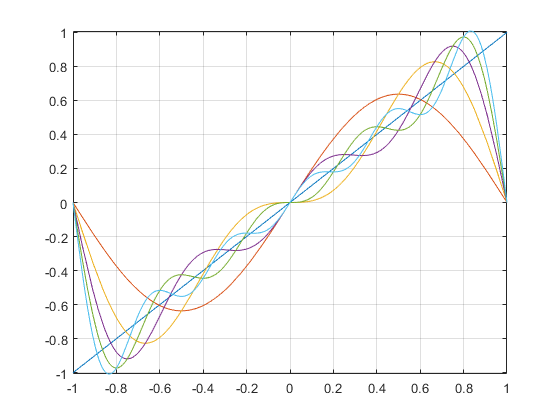


fplot(f(x),[-1 1]);
hold on;
grid on;

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-1 1])
    grid on
end
hold off

f1

$$f1 = \frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }+\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }-\frac{\sin\left(4\,\pi \,x\right)}{2\,\pi }+\frac{2\,\sin\left(5\,\pi \,x\right)}{5\,\pi }$$

% (2*sin(pi*x))/pi - sin(2*pi*x)/pi + (2*sin(3*pi*x))/(3*pi) - sin(4*pi*x)/(2*pi) + (2*sin(5*pi*x))/(5*pi)

a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & \frac{2}{\pi } & \frac{2\,\sin\left(\pi \,x\right)}{\pi }\\ 2 & 0 & -\frac{1}{\pi } & -\frac{\sin\left(2\,\pi \,x\right)}{\pi }\\ 3 & 0 & \frac{2}{3\,\pi } & \frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }\\ 4 & 0 & -\frac{1}{2\,\pi } & -\frac{\sin\left(4\,\pi \,x\right)}{2\,\pi }\\ 5 & 0 & \frac{2}{5\,\pi } & \frac{2\,\sin\left(5\,\pi \,x\right)}{5\,\pi } \end{array}\right)$$

% [ 1, 0,      2/pi,       (2*sin(pi*x))/pi]
% [ 2, 0,     -1/pi,        -sin(2*pi*x)/pi]
% [ 3, 0,  2/(3*pi), (2*sin(3*pi*x))/(3*pi)]
% [ 4, 0, -1/(2*pi),    -sin(4*pi*x)/(2*pi)]
% [ 5, 0,  2/(5*pi), (2*sin(5*pi*x))/(5*pi)]


function [a0,a,b,abf]=fourierseriesL(f,L)
syms x real
syms m integer

a0=(1/L)*int(f(x),x,-L,L);
a(m)=(1/L)*int(f*cos(m*pi*x/L),x,-L,L);
a(m)=simplify(subs(a(m),[sin(pi*m),sin((pi*m)/2)^2,cos(pi*m)],...
    [0,(1-(-1)^m)/2,(-1)^m]));
af(m)=a(m)*cos(m*pi*x/L);

b(m)=(1/L)*int(f*sin(m*pi*x/L),x,-L,L);
b(m)=simplify(subs(b(m),[sin(pi*m),sin((pi*m)/2)^2,cos(pi*m)],...
    [0,(1-(-1)^m)/2,(-1)^m]));
bf(m)=b(m)*sin(m*pi*x/L);
abf(m)=af(m)+bf(m);
end